syms s t;

tt = 0:0.05:15;
G1 = 1/((s+2)*(s+3));
y = ilaplace(G1/s , s , t)

$$y = \frac{{\mathrm{e}}^{-3\,t}}{3}-\frac{{\mathrm{e}}^{-2\,t}}{2}+\frac{1}{6}$$

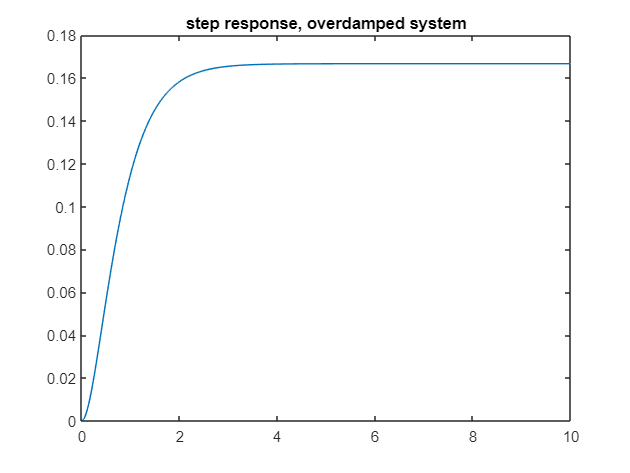

y_num = double(subs(y, t, tt));
figure;
plot(tt,y_num);
xlim([0 10]);
title("step response, overdamped system");

tt = 0:0.05:15;
G1 = 1/((s+1)*(s+1));
y = ilaplace(G1/s , s , t)

$$y = 1-t\,{\mathrm{e}}^{-t}-{\mathrm{e}}^{-t}$$

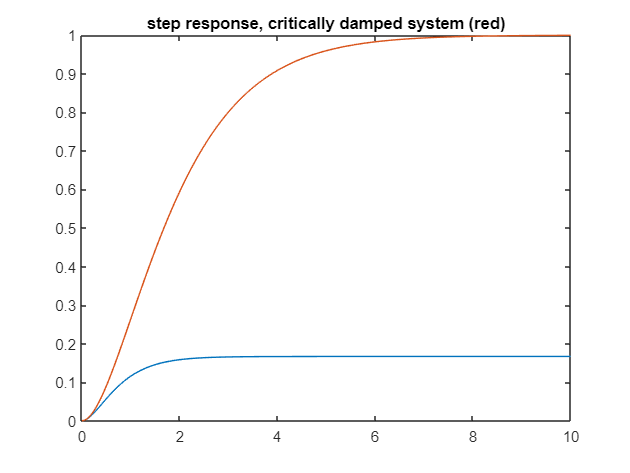

y_num = double(subs(y, t, tt));
% figure;
hold on
plot(tt,y_num);
xlim([0 10]);
title("step response, critically damped system (red)");